# Actividad 8.1_2

### Diego Garcia Rueda

#### **Obtener **la matriz de  transformación **homogénea  T  **de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base).

Primero se realizan los comandos de limpieza de pantalla y de workspace.

clear all
close all
clc

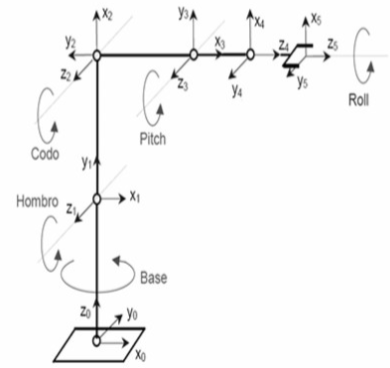

Se calculan las matrices de transformación Homogénea del modelo, en este caso las longitudes de la base al hombre, del hombro al codo, y del codo a la siguiente junta tendran un valor de 2, a partir de las siguientes juntas, todas tendran un desplazamiento con un valor de 1. Las transformaciones son las siguientes:

m2_H0 = SE3;
m2_H1 = SE3(rotx(pi/2), [0,0,2]);
m2_H2 = SE3(rotz(pi/2), [0,2,0]);
m2_H3 = SE3(rotz(-pi/2), [0,-2,0]);
%La siguiente trasnsformación es una doble rotación con una traslación por
%lo que se separaran en 2 transformaciones diferentes:
m2_H4 = SE3(rotz(pi/2), [0,0,0]);
m2_H5 = SE3(rotx(pi/2), [0,-1,0]);

m2_H6 = SE3(roty(0), [0,0,1]);

Se realizan las matrices de transformación globales.

m2_H20 = m2_H1 * m2_H2;
m2_H30 = m2_H20 * m2_H3;
m2_H40 = m2_H30 * m2_H4;
m2_H50 = m2_H40 * m2_H5;
m2_H60 = m2_H50 * m2_H6;

Se establecen valores para los 3 ejes, estas seran las coordenadas con las traslaciones y las rotaciones de todas las transformaciones:

plot3(0, 0, 0); axis([-6 6 -6 6 -6 6]); grid on;
hold on;

Se establece la trama absoluta o global y posteriormente se realizan las animaciones para cada una de las tramas:

trplot(m2_H0,'rgb','axis', [-6 6 -6 6 -6 6])

%Primera trama

pause;
tranimate(m2_H0, m2_H1,'rgb','axis', [-6 6 -6 6 -6 6])
%Segunda trama
pause;
tranimate(m2_H1, m2_H20,'rgb','axis', [-6 6 -6 6 -6 6])
%Tercera trama
pause;
tranimate(m2_H20, m2_H30,'rgb','axis', [-6 6 -6 6 -6 6])
%Cuarta trama
pause;
tranimate(m2_H30, m2_H40,'rgb','axis', [-6 6 -6 6 -6 6])
%Quinta trama
pause;
tranimate(m2_H40, m2_H50,'rgb','axis', [-6 6 -6 6 -6 6])
%Sexta trama
pause;
tranimate(m2_H50, m2_H60,'rgb','axis', [-6 6 -6 6 -6 6])


disp(m2_H60)

    0         0         1         4
    0        -1         0         0
    1         0         0         4
    0         0         0         1
